HW3

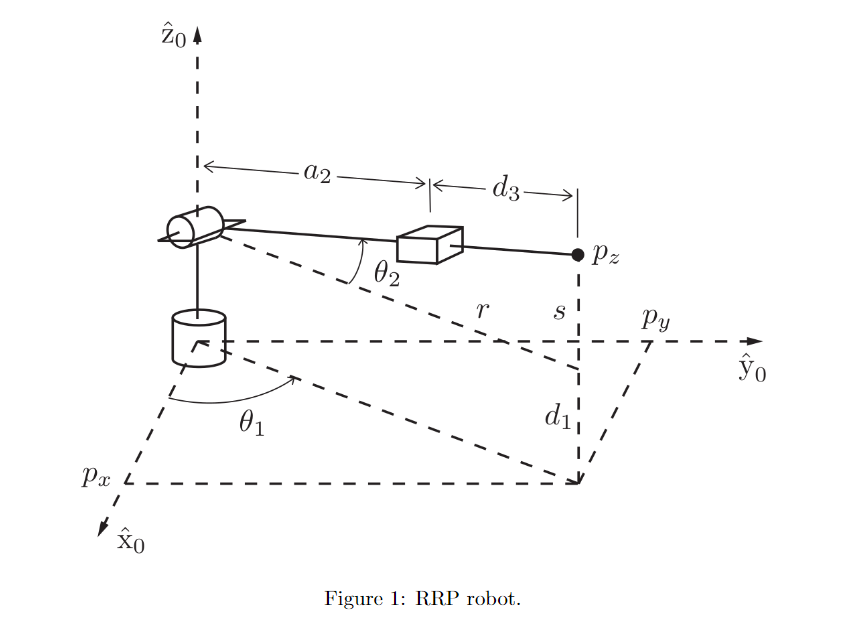

## Forward kinematics

syms q1 q2 d3 
d1 = 1

d1 = 1

a2 = 1

a2 = 1

H = Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3)

$$H = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{2}+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{1} & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{1}+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 1-d_{3}\,\sin\left(q_{2}\right)-\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

simplify(H)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 1-d_{3}\,\sin\left(q_{2}\right)-\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H =  Rz(0) * Tz(d1) * Ry(0) * Tx(a2) * Tx(0)

H =      1     0     0     1
     0     1     0     0
     0     0     1     1
     0     0     0     1


## Inverse kinematics

% 4 possible solutions
% 1st Solution
clear 
d1 = 1

d1 = 1

a2 = 1

a2 = 1

H =  Rz(-pi/1.5) * Tz(d1) * Ry(-pi/1.5) * Tx(a2) * Tx(5)

H =     0.2500    0.8660    0.4330    1.5000
    0.4330   -0.5000    0.7500    2.5981
    0.8660         0   -0.5000    6.1962
         0         0         0    1.0000


% q1 = atan2 ( y , x)
x =  H(1,4)

x = 1.5000

y =  H(2,4)

y = 2.5981

z=  H(3,4)

z = 6.1962

q1 = atan2 (y , x)

q1 = 1.0472

% q2 = atan2 ( (d1 - z) / sqrt(x^2+y^2) )
q2 = atan2 ( (d1-z) , sqrt(x^2+y^2) )

q2 = -1.0472


% d3 = sqrt( (x^2 + y^2) + (d1 - z)^2 ) - a2
d3 = sqrt( (x^2 + y^2) + (d1 - z)^2 ) - a2

d3 = 5.0000


H =  Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3)

H =     0.2500   -0.8660   -0.4330    1.5000
    0.4330    0.5000   -0.7500    2.5981
    0.8660         0    0.5000    6.1962
         0         0         0    1.0000


% 2nd solution
q1_2 = q1;
q2_2 = q2 + pi;
d3_2 = -(d3 + 2*a2);
H2 =  Rz(q1_2) * Tz(d1) * Ry(q2_2) * Tx(a2) * Tx(d3_2);

% 3rd solution
q1_3 = q1 + pi;
q2_3 = -q2 +pi;
d3_3 = d3 ;
H3 =  Rz(q1_3) * Tz(d1) * Ry(q2_3) * Tx(a2) * Tx(d3_3);

% 4th solution
q1_4 = q1 + pi;
q2_4 = -q2 ;
d3_4 = -(d3 + 2*a2);
H4 =  Rz(q1_4) * Tz(d1) * Ry(q2_4) * Tx(a2) * Tx(d3_4);

H

H =     0.2500   -0.8660   -0.4330    1.5000
    0.4330    0.5000   -0.7500    2.5981
    0.8660         0    0.5000    6.1962
         0         0         0    1.0000


H2

H2 =    -0.2500   -0.8660    0.4330    1.5000
   -0.4330    0.5000    0.7500    2.5981
   -0.8660         0   -0.5000    6.1962
         0         0         0    1.0000


H3

H3 =     0.2500    0.8660    0.4330    1.5000
    0.4330   -0.5000    0.7500    2.5981
    0.8660         0   -0.5000    6.1962
         0         0         0    1.0000


H4

H4 =    -0.2500    0.8660   -0.4330    1.5000
   -0.4330   -0.5000   -0.7500    2.5981
   -0.8660         0    0.5000    6.1962
         0         0         0    1.0000


%test
flag=0;
d1 = 1;
a2 = 1;
iterations=0;
for i= -2*pi:0.1:2*pi
    for j= -2*pi:0.1:2*pi

        H =  Rz(i) * Tz(d1) * Ry(j) * Tx(a2) * Tx(1);
        % q1 = atan2 ( y , x)
        x =  H(1,4);
        y =  H(2,4);
        z=  H(3,4);
        q1 = atan2 (y , x);
        % q2 = atan2 ( (d1 - z) / sqrt(x^2+y^2) )
        q2 = atan2 ( (d1 - z) , sqrt(x^2+y^2) );
        % d3 = sqrt( (x^2 + y^2) + (d1 - z)^2 ) - a2
        d3 = sqrt( (x^2 + y^2) + (d1 - z)^2 ) - a2;
        
        H1 =  Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3);
       % 2nd solution
        q1_2 = q1;
        q2_2 = q2 + pi;
        d3_2 = -(d3 + 2*a2);
        H2 =  Rz(q1_2) * Tz(d1) * Ry(q2_2) * Tx(a2) * Tx(d3_2);
        % 3rd solution
        q1_3 = q1 + pi;
        q2_3 = -q2 +pi;
        d3_3 = d3 ;
        H3 =  Rz(q1_3) * Tz(d1) * Ry(q2_3) * Tx(a2) * Tx(d3_3);
        % 4th solution
        q1_4 = q1 + pi;
        q2_4 = -q2 ;
        d3_4 = -(d3 + 2*a2);
        H4 =  Rz(q1_4) * Tz(d1) * Ry(q2_4) * Tx(a2) * Tx(d3_4);
        m= abs(H1-H) <= 1e-3*ones(4);
        n= abs(H2-H) <= 1e-3*ones(4);
        l= abs(H3-H) <= 1e-3*ones(4);
        o= abs(H4-H) <= 1e-3*ones(4);
        if all(m(:)) | all(n(:))|all(o(:))|all(l(:))
            fprintf('equality at q1= %f and q2= %f \n',i,j);
            flag=flag+1;
        end
        iterations=iterations+1;
    end   
end

equality at q1= -6.283185 and q2= -6.283185 
equality at q1= -6.283185 and q2= -6.183185 
equality at q1= -6.283185 and q2= -6.083185 
equality at q1= -6.283185 and q2= -5.983185 
equality at q1= -6.283185 and q2= -5.883185 
equality at q1= -6.283185 and q2= -5.783185 
equality at q1= -6.283185 and q2= -5.683185 
equality at q1= -6.283185 and q2= -5.583185 
equality at q1= -6.283185 and q2= -5.483185 
equality at q1= -6.283185 and q2= -5.383185 
equality at q1= -6.283185 and q2= -5.283185 
equality at q1= -6.283185 and q2= -5.183185 
equality at q1= -6.283185 and q2= -5.083185 
equality at q1= -6.283185 and q2= -4.983185 
equality at q1= -6.283185 and q2= -4.883185 
equality at q1= -6.283185 and q2= -4.783185 
equality at q1= -6.283185 and q2= -4.683185 
equality at q1= -6.283185 and q2= -4.583185 
equality at q1= -6.283185 and q2= -4.483185 
equality at q1= -6.283185 and q2= -4.383185 
equality at q1= -6.283185 and q2= -4.283185 
equality at q1= -6.283185 and q2= -4.183185 
equality a

fprintf('flag = %d',flag);

flag = 15876

fprintf('iterations = %d',iterations);

iterations = 15876

% if flags == iterations then the inverse solutions are working fine

## Jacobian

## numerical method

clear 
d1 = 1

d1 = 1

a2 = 1

a2 = 1

syms q1 q2 d3
H =  Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3)

$$H = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{2}+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{1} & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{1}+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 1-d_{3}\,\sin\left(q_{2}\right)-\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

% rotation matrix of the end effector
R = H(1:3,1:3);
% the inverse of the rotation matrix
R_i = [R^-1 zeros(3,1);0 0 0 1];
% get the jacobian of the first joint
J1r = Rzd(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3) * R_i;
J1r = simplify(J1r)

$$J1r = \left(\begin{array}{cccc} 0 & -1 & 0 & -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right)\\ 1 & 0 & 0 & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right)\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% get the jacobian elements
J1 = [ J1r(1,4) J1r(2,4) J1r(3,4) J1r(3,2) J1r(1,3) J1r(2,1)].'

$$J1 = \left(\begin{array}{c} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

 %2nd joint

J2r = Rz(q1) * Tz(d1) * Ryd(q2) * Tx(a2) * Tx(d3) * R_i;
J2r = simplify(J2r)

$$J2r = \left(\begin{array}{cccc} 0 & 0 & \cos\left(q_{1}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right)\\ 0 & 0 & \sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right)\\ -\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & -\cos\left(q_{2}\right)\,\left(d_{3}+1\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% get the jacobian elements
J2 = [ J2r(1,4) J2r(2,4) J2r(3,4) J2r(3,2) J2r(1,3) J2r(2,1)].'

$$J2 = \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right)\\ -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right)\\ -\cos\left(q_{2}\right)\,\left(d_{3}+1\right)\\ -\sin\left(q_{1}\right)\\ \cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

%3rd joint

J3p = Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Txd(d3) * R_i;
J3p = simplify(J3p)

$$J3p = \left(\begin{array}{cccc} 0 & 0 & 0 & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0 & 0 & 0 & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & 0 & 0 & -\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

% get the jacobian elements
J3 = [ J3p(1,4) J3p(2,4) J3p(3,4) J3p(3,2) J3p(1,3) J3p(2,1)].'

$$J3 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right)\\ 0\\ 0\\ 0 \end{array}\right)$$

% Full jacobian
J = [simplify(J1) simplify(J2) simplify(J3)]

$$J = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

## 2nd method Skew Theory

syms q1 q2 d3
assume(q1,'real')
assume(q2,'real')
assume(d3,'real')
T00 = eye(4)

T00 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


T01 = Rz(q1) * Tz(d1)

$$T01 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = Rz(q1) * Tz(d1) * Ry(q2)

$$T02 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3)

$$T03 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{2}+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \sigma_{1} & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sigma_{1}+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & 1-d_{3}\,\sin\left(q_{2}\right)-\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{2}=\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

O0 = T00(1:3,4)

O0 =      0
     0
     0


O1 = T01(1:3,4)

$$O1 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

O2 = T02(1:3,4)

$$O2 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

O3 = T03(1:3,4)

$$O3 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 1-d_{3}\,\sin\left(q_{2}\right)-\sin\left(q_{2}\right) \end{array}\right)$$

z0 = T00(1:3,3) %Rz

z0 =      0
     0
     1


z1 = T01(1:3,2) %Ry

$$z1 = \left(\begin{array}{c} -\sin\left(q_{1}\right)\\ \cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

z2 = T02(1:3,1) %Tx

$$z2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) \end{array}\right)$$

Full Jacobian

for revolute joint:


$$J_i =\left\lbrack \begin{array}{c}
Z_{i-1} \times \left(O_n -O_{i-1} \right)\\
Z_{i-1} 
\end{array}\right\rbrack$$


for prismatic joint:


$$J_i =\left\lbrack \begin{array}{c}
Z_{i-1} \\
0
\end{array}\right\rbrack$$


J1_s = [cross(z0,(O3 - O0)); z0]

$$J1\_s = \left(\begin{array}{c} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ 0\\ 0\\ 0\\ 1 \end{array}\right)$$

J2_s = [cross(z1,(O3-O1)); z1]

$$J2\_s = \begin{array}{l} \left(\begin{array}{c} -\cos\left(q_{1}\right)\,\sigma_{1}\\ -\sin\left(q_{1}\right)\,\sigma_{1}\\ -\cos\left(q_{1}\right)\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+d_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\right)-\sin\left(q_{1}\right)\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+d_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\right)\\ -\sin\left(q_{1}\right)\\ \cos\left(q_{1}\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(q_{2}\right)+d_{3}\,\sin\left(q_{2}\right) \end{array}$$

J3_s = [z2;0;0;0]

$$J3\_s = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right)\\ 0\\ 0\\ 0 \end{array}\right)$$

J_full = [simplify(J1_s) simplify(J2_s) simplify(J3_s)]

$$J\_full = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

J_full = simplify(J_full)

$$J\_full = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

test = simplify(J - J_full)

$$test = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

3rd method partial derivative

d1 = 1;
a2 = 1;
syms q1 q2 d3
assume(q1,'real')
assume(q2,'real')
assume(d3,'real')
H =  simplify(Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3));
% prepare the derivative matrix
H_dot = sym('A', [6 3]);
% get the first 3 rows
for r = 1:3
    H_dot(r,1) = diff(H(r,4),q1);
    H_dot(r,2) = diff(H(r,4),q2);
    H_dot(r,3) = diff(H(r,4),d3);
end
% get q1 rotation
T = simplify(Rzd(q1)*inv(Rz(q1)));
H_dot(4:6,1) = [T(3,2) T(1,3) T(2,1)] ;
% get q1 rotation
T = simplify(Rz(q1)*Ryd(q2)*inv(Rz(q1)*Ry(q2)));
H_dot(4:6,2) = [T(3,2) T(1,3) T(2,1)] ;
% get q1 rotation
T = simplify(Rz(q1)*Ry(q2)*Txd(d3)*inv(Rz(q1)*Ry(q2)*Tx(d3)));
H_dot(4:6,3) = [T(3,2) T(1,3) T(2,1)] 

$$H\_dot = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(d_{3}+1\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(d_{3}+1\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(d_{3}+1\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\cos\left(q_{2}\right)-d_{3}\,\cos\left(q_{2}\right) & -\sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

% Test the partial derivative method

test2 = simplify(H_dot - J_full)

$$test2 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

## Singularity Analysis

clear
syms q1 q2 d3 d1 a2 
assume(q1,'real')
assume(q2,'real')
assume(d3,'real')
H =  simplify(Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3));
% prepare the derivative matrix
H_dot = sym('A', [6 3]);
% get the first 3 rows
for r = 1:3
    H_dot(r,1) = diff(H(r,4),q1);
    H_dot(r,2) = diff(H(r,4),q2);
    H_dot(r,3) = diff(H(r,4),d3);
end
% get q1 rotation
T = simplify(Rzd(q1)*inv(Rz(q1)));
H_dot(4:6,1) = [T(3,2) T(1,3) T(2,1)] ;
% get q1 rotation
T = simplify(Rz(q1)*Ryd(q2)*inv(Rz(q1)*Ry(q2)));
H_dot(4:6,2) = [T(3,2) T(1,3) T(2,1)] ;
% get q1 rotation
T = simplify(Rz(q1)*Ry(q2)*Txd(d3)*inv(Rz(q1)*Ry(q2)*Tx(d3)));
H_dot(4:6,3) = [T(3,2) T(1,3) T(2,1)] 

$$H\_dot = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -a_{2}\,\cos\left(q_{2}\right)-d_{3}\,\cos\left(q_{2}\right) & -\sin\left(q_{2}\right)\\ 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

% singularity occurs when the
% determinant ( Jacobian ) = 0
simplify(H_dot)

$$ans = \left(\begin{array}{cccccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & 0 & 0 & 0\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & 0 & 0 & 0\\ 0 & -\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(q_{2}\right) & 0 & 0 & 0\\ 0 & -\sin\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 0 & \cos\left(q_{1}\right) & 0 & 0 & 0 & 0\\ 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

J_simplified = H_dot(1:3,1:3)

$$J\_simplified = \left(\begin{array}{ccc} -\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(a_{2}+d_{3}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(a_{2}+d_{3}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -a_{2}\,\cos\left(q_{2}\right)-d_{3}\,\cos\left(q_{2}\right) & -\sin\left(q_{2}\right) \end{array}\right)$$

eqn = simplify(det(J_simplified)) == 0

$$eqn = -\cos\left(q_{2}\right)\,{\left(a_{2}+d_{3}\right)}^{2}=0$$

S = solve(eqn,q2,d3,'Real',true)

S = struct with fields:
    q2: [2×1 sym]
    d3: [2×1 sym]


S.q2

$$ans = \left(\begin{array}{c} 0\\ \frac{\pi }{2} \end{array}\right)$$

S.d3

$$ans = \left(\begin{array}{c} -a_{2}\\ 0 \end{array}\right)$$

clear
a2 = 1

a2 = 1

d1 =1

d1 = 1

q1 = 0

q1 = 0

q2 = 0

q2 = 0

d3 = a2

d3 = 1

H =  Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3)

H =      1     0     0     2
     0     1     0     0
     0     0     1     1
     0     0     0     1


% rotation matrix of the end effector
R = H(1:3,1:3);
% the inverse of the rotation matrix
R_i = [R^-1 zeros(3,1);0 0 0 1];
% get the jacobian of the first joint
J1r = Rzd(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Tx(d3) * R_i;

% get the jacobian elements
J1 = [ J1r(1,4) J1r(2,4) J1r(3,4) J1r(3,2) J1r(1,3) J1r(2,1)].'

J1 =      0
     2
     0
     0
     0
     1



J2r = Rz(q1) * Tz(d1) * Ryd(q2) * Tx(a2) * Tx(d3) * R_i;

% get the jacobian elements
J2 = [ J2r(1,4) J2r(2,4) J2r(3,4) J2r(3,2) J2r(1,3) J2r(2,1)].'

J2 =      0
     0
    -2
     0
     1
     0



J3p = Rz(q1) * Tz(d1) * Ry(q2) * Tx(a2) * Txd(d3) * R_i;

% get the jacobian elements
J3 = [ J3p(1,4) J3p(2,4) J3p(3,4) J3p(3,2) J3p(1,3) J3p(2,1)].'

J3 =      1
     0
     0
     0
     0
     0


% Full jacobian
J = [J1 J2 J3]

J =      0     0     1
     2     0     0
     0    -2     0
     0     0     0
     0     1     0
     1     0     0


det(J(1:3,1:3))

ans = -4